Load data from home page

load("A_Homepage.mat")

Scale input to avoid clipping

audio = audio/max(abs(audio));

Apply gain to audio

wet = gain*audio;

Apply filter using tone parameter

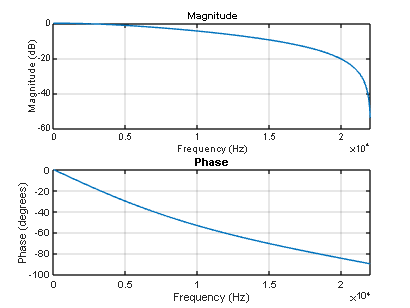

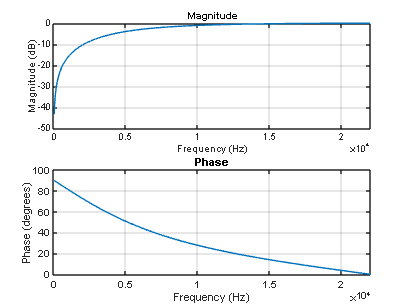

% Low pass for low tones
fcl = 8000;
[ZL,PL,KL] = butter(1, fcl/(fs/2), 'low');

% High pass for high tones
fch = 2000;
[ZH,PH,KH] = butter(1, fch/(fs/2), 'high');

% Convert ZPK models to transfer functions
[BL,AL] = zp2tf(ZL, PL, KL);
[BH,AH] = zp2tf(ZH, PH, KH);


% Apply tone setting
wet = (1 - tone)*filter(BL, AL, wet) + tone*filter(BH, AH, wet);

Generate output as the wet signal.

output = wet;

Save output to a .mat file.

save("effectoutput.mat", "output", "fs", "effect", ...
    "WriteNewFile", "PlayAudio")
clear